**W12AIR-SM0721P Artificial Neural Networks **- Projekt

# Wine quality classification using Artificial Neural Network

Authors: P.Ozga 

dataset from: by Andrewmchen and Mateiz from github link: https://github.com/mlflow/mlflow-example/blob/master/wine-quality.csv

dataset from: by `Mustanger from kaggle link:`

https://www.kaggle.com/code/eisgandar/red-wine-quality-eda-classification/input

### Toolbox: Statistics and Machine Learning & Deep Learning

## 1. Data loading and Display

close all; 
fpath = fullfile(pwd,'wine-quality_dataset-kopia.csv');            % File path
fname = readtable(fpath, 'VariableNamingRule', 'preserve');      % Correct read file
firstFive = head(fname, 5);                                      % Display first 5 rows
verticalView = array2table(firstFive.Variables', ...
    'VariableNames', strcat("Sample ", string(1:5)), ...
    'RowNames', fname.Properties.VariableNames);
disp(verticalView);

                            Sample 1    Sample 2    Sample 3    Sample 4    Sample 5
                            ________    ________    ________    ________    ________

    fixed acidity                7         6.3          8.1         7.2         7.2 
    volatile acidity          0.27         0.3         0.28        0.23        0.23 
    citric acid               0.36        0.34          0.4        0.32        0.32 
    residual sugar            20.7         1.6          6.9         8.5         8.5 
    chlorides                0.045       0.049         0.05       0.058       0.058 
    free sulfur dioxide         45          14           30          47          47 
    total sulfur dioxide      

Table 1.1 Wine characteristics- first 5 samples

% DEBUG NAMES
if isempty(fname.Properties.VariableNames)
    disp('Warning: The dataset lacks variable names!');
end

## **2. Data Verification**

nonNumericCols = varfun(@isnumeric, fname);                 % Check each columns
nonNumericColsNames = fname.Properties.VariableNames(~all(nonNumericCols{:, :}, 1));
if ~isempty(nonNumericColsNames)                            %is numeric or no-numeric?
    disp('Database is non-numeric.');
    disp(nonNumericColsNames);
else
    disp('Each columns is numeric.');
    numRows = height(fname);                                % or: size(fname, 1);
end

Each columns is numeric.


## 3. Dataset Statistics Calculation

numericCols = varfun(@isnumeric, fname, 'OutputFormat', 'uniform');
numericData = fname(:, numericCols);

dataArray = numericData{:,:};

countVals = sum(~ismissing(dataArray))';                    % Compute statistic
minVals   = min(dataArray)';
p25Vals   = prctile(dataArray, 25)';
p50Vals   = prctile(dataArray, 50)';
p75Vals   = prctile(dataArray, 75)';
meanVals  = mean(dataArray)';
stdVals   = std(dataArray)';
maxVals   = max(dataArray)';

                                                            % Create table
summaryVertical = table(countVals, minVals, p25Vals, p50Vals, p75Vals, meanVals, stdVals, maxVals, ...
    'VariableNames', {'Count','Min','P25%','P50%','P75%','Mean','Std','Max'}, ...
    'RowNames', numericData.Properties.VariableNames);
summaryVertical = round(summaryVertical, 3);  % Zaokrąglenie do 3 miejsc po przecinku

% Count: The number of non-missing (valid) entries in each column of the dataset.
% Min: The minimum value in each numerical column.
% P25%: The 25th percentile value (also known as the first quartile), which is the value below which 25% of the data falls.
% P50%: The 50th percentile value (median), which divides the data into two equal halves.
% P75%: The 75th percentile value (also known as the third quartile), where 75% of the data points fall below this value.
% Mean: The average value of the data in each column.
% Std: The standard deviation, which measures the amount of variation or dispersion of the data.
% Max: The maximum value in each numerical column.
disp(summaryVertical);

                            Count     Min     P25%     P50%     P75%      Mean      Std       Max 
                            _____    _____    _____    _____    _____    ______    ______    _____

    fixed acidity           4898       3.8      6.3      6.8      7.3     6.855     0.844     14.2
    volatile acidity        4898      0.08     0.21     0.26     0.32     0.278     0.101      1.1
    citric acid             4898         0     0.27     0.32     0.39     0.334     0.121     1.66
    residual sugar          4898       0.6      1.7      5.2      9.9     6.391     5.072     65.8
    chlorides               4898     0.009    0.

Table 3.1 Count values Min, Max, Mean

## 4. Sample Selection for Each Quality Class

validClasses = 4:8;                                                 % Define classes
samples = {};                                                       % initial empty list of samples

for i = 1:length(validClasses)
    quality_class = validClasses(i);
    sample = fname(fname.quality == quality_class, :);
    samples{i} = sample(1, :);                                      % for first sample
end

%DEBUG IF QUALITY NOT FOUND
if ~ismember('quality', fname.Properties.VariableNames)
    error('Quality column not found in the dataset');
end

samples_table = vertcat(samples{:});                                % sum samples and create horizontal table
samples_transposed = array2table(samples_table.Variables', ...
    'VariableNames', strcat("Class ", string(validClasses)), ...  
    'RowNames', samples_table.Properties.VariableNames);
disp(samples_transposed);

                            Class 4    Class 5    Class 6    Class 7    Class 8
                            _______    _______    _______    _______    _______

    fixed acidity              6.2        8.1          7        6.6        6.2 
    volatile acidity          0.45       0.27       0.27       0.16       0.66 
    citric acid               0.26       0.41       0.36        0.4       0.48 
    residual sugar             4.4       1.45       20.7        1.5        1.2 
    chlorides                0.063      0.033      0.045      0.044      0.029 
    free sulfur dioxide         63         11         45         48         29 
    total sulfur dioxide       206         63        170        143   

Table 4.1 Sample selection for 7 classes

## 5. Class Distribution

qualityCounts = countcats(categorical(fname.quality));
uniqueClasses = unique(fname.quality);
for i = 1:length(uniqueClasses)
    fprintf('Class %d has %d samples\n', uniqueClasses(i), qualityCounts(i));
end

Class 3 has 20 samples
Class 4 has 163 samples
Class 5 has 1457 samples
Class 6 has 2198 samples
Class 7 has 880 samples
Class 8 has 175 samples
Class 9 has 5 samples


Table 5.1 Class Distribution

## 6. Normalization input

Features4 = {'alcohol', 'volatile acidity', 'sulphates', 'citric acid'};
%X = fname{:, Features4};  % Only the 4 selected features
X =fname{:,1:end-1};                                                    % for all features
Y = fname{:, 12};                                                       % Quality rating (12th column)
X = normalize(X, 'range');                                              % Min-Max normalization

! Min-max normalization: Guarantees all features will have the exact same scale but does not handle outliers well.

! Z-score normalization: Handles outliers, but does not produce normalized data with the exact same scale ex. scale OX [1:1] and for OY [2:2]

## 7. Labels Encoding (One-hot Encoding)

Y_cat = categorical(Y);
Y_encoded = dummyvar(Y_cat);                                            % One-hot encoding

# Training and Testing Neural Network

## 8. Data Splitting

about` cvpartition function`, link: https://ch.mathworks.com/help/stats/cvpartition.html

cv = cvpartition(Y_cat,'Holdout',0.2);                                  % two set
X_train = X(training(cv),:);
Y_train = Y_encoded(training(cv),:);
X_test = X(test(cv), :);
Y_test =Y_encoded(test(cv), :);

## 9. Build MLP (Multilayer Perceptron) Network:

classWeights = [5, 1, 1, 1, 1, 1, 10];                                   % random weights

X_train_weighted = X_train;

net = patternnet([90, 40]);                                             % Hidden layers
net.trainFcn = 'trainscg';                                              % Scaled conjugate gradient
net.layers{end}.transferFcn = 'softmax';                                % Last layers = output = classification
net.performFcn = 'crossentropy';                                        % Function of cost

% Oblicz liczbę wystąpień każdej klasy w Y_train
Y_train_classes = vec2ind(Y_train')';  % Zamień one-hot na indeksy klas
classLabels = unique(Y_train_classes);
numSamplesPerClass = histcounts(Y_train_classes, [classLabels; max(classLabels)+1]);

% Wylicz odwrotność częstości jako wagi klas (często dzielone przez max dla stabilności)
classWeights = 1 ./ numSamplesPerClass;
classWeights = classWeights / max(classWeights);  % Normalizacja do zakresu [0,1]

X_train_weighted = X_train_weighted';  % Rozmiar [11 x 3919]
Y_train = Y_train';  % Rozmiar [7 x 3919]
% Dla każdej próbki treningowej przypisz wagę zależną od klasy
sampleWeights = classWeights(Y_train_classes)';

net.trainParam.showWindow = false; 
[net, tr] = train(net, X_train_weighted, Y_train,[],[], sampleWeights);
%[net, tr] = train(net, X_train_weighted', Y_train');                    % Train, add weights

## 10. Prediction and Evaluation

Y_pred = net(X_test');
Y_pred_class = vec2ind(Y_pred);                                         % Change from one-hot to class index
Y_test_class = vec2ind(Y_test');

correct = (Y_pred_class == Y_test_class);  

test_classes = vec2ind(Y_test')';
testWeights = classWeights(test_classes)';
correct = (Y_pred_class' == test_classes);
weightedAccuracy = sum(correct .* testWeights) / sum(testWeights);

fprintf('Weighted Accuracy: %.2f%%\n', weightedAccuracy * 100);

Weighted Accuracy: 22.81%


## 11. Confusion Matrix

cm = confusionmat(Y_test_class, Y_pred_class);
precision = diag(cm)./sum(cm,2);
recall = diag(cm)./sum(cm,1)';
f1 = 2 * (precision .* recall) ./ (precision + recall);                             % F1- score
macroF1 = mean(f1(~isnan(f1)));
% figure(4);
% bar(macroF1);
% xlabel('Macro F1- score');
% ylabel('Macro F1- score');
fprintf('Macro F1-score: %.2f\n', macroF1);

Macro F1-score: 0.40


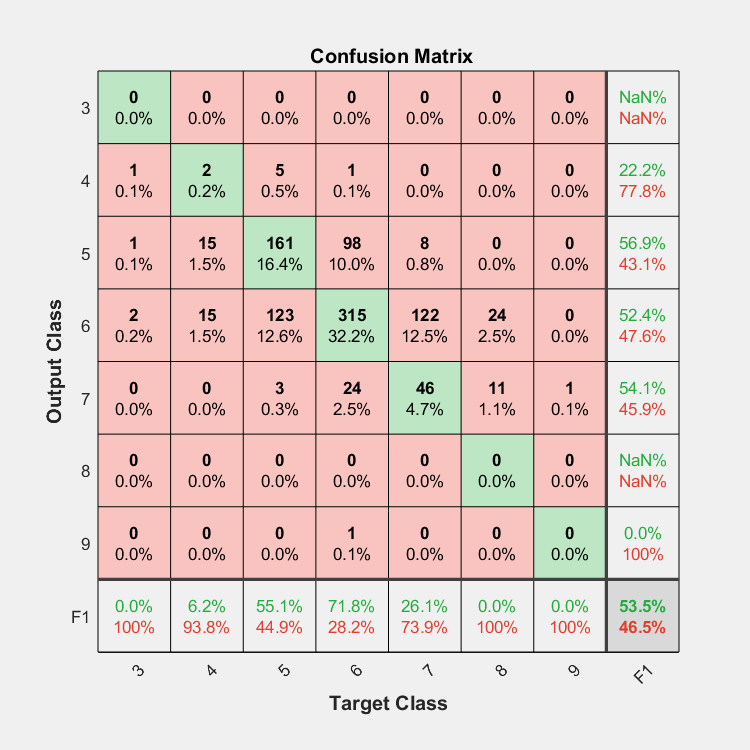

figure(1);
numClasses = size(Y_encoded, 2); 
Y_test_vec = full(ind2vec(Y_test_class, numClasses));
Y_pred_vec = full(ind2vec(Y_pred_class, numClasses));
plotconfusion(Y_test_vec, Y_pred_vec);
classLabels = {'3','4','5','6','7','8','9','F1'};
ax = gca;
ax.XTickLabel = classLabels;
ax.YTickLabel = classLabels;

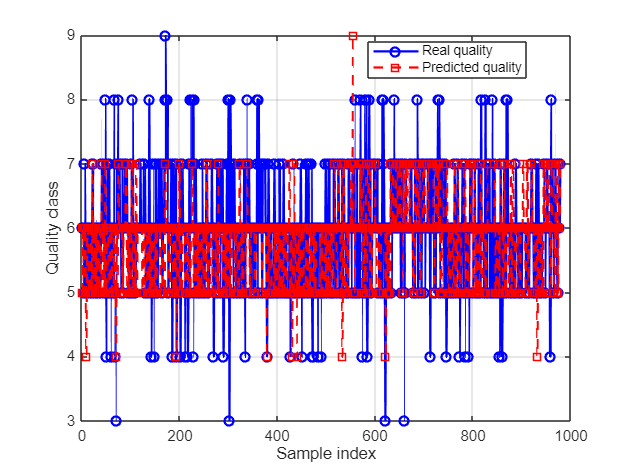

figure(2);
plot(Y_test_class, 'b-o', 'LineWidth', 1.5); hold on;
plot(Y_pred_class, 'r--s', 'LineWidth', 1.5);
legend('Real quality', 'Predicted quality', 'Location', 'best');
xlabel('Sample index');
ylabel('Quality class');
classLabels = {'3','4','5','6','7','8','9','F1'};
ax = gca;
%ax.XTickLabel = classLabels;
ax.YTickLabel = classLabels;
grid on;

drawnow;                                                                % debugging while buffering
pause(20);